This scrip is to use to find the best-fitted time step between simulation and experiment.

pls change the **simMSDType** variable, and input the **expMSDData** manually(C:\Users\zhouquan\OneDrive\research\scrips\processed_data).

a=[0];[0];[0];
simMSDType='twoStage V1=1000(r-2); V2=0.2r^2';
expMSDType='p47 mix discard';
a(1)=70.13;%noForcefield
a(2)=0.008762;
a(3)=-72.44;
fun=inline('max(a(1)*t^a(2)+a(3),0)','a','t');
%disp(fun(a,2e5))
%disp(fun(a,5e5))

t_exp=t_mixMSD(1,:);
MSD_exp=t_mixMSD(2,:);

%b_scale=[1,2,5,10,100,200,500,1000,2e3,5e3,1e4,2e4,5e4,1e5];
b_scale=10:10:10000;
residual_list=[];
residual_min=1e100;
for b=b_scale
    residual=0;
    for t=1:length(t_exp)
        residual=residual+(2.56e-14*(fun(a,t_exp(t)*b))-MSD_exp(t)*1e-18)^2;
    end
    %select the min residual b
    if residual<=residual_min
        b_min=b;
        residual_min=residual;
    end
    residual_list=[residual_list;residual];
end

residual figure

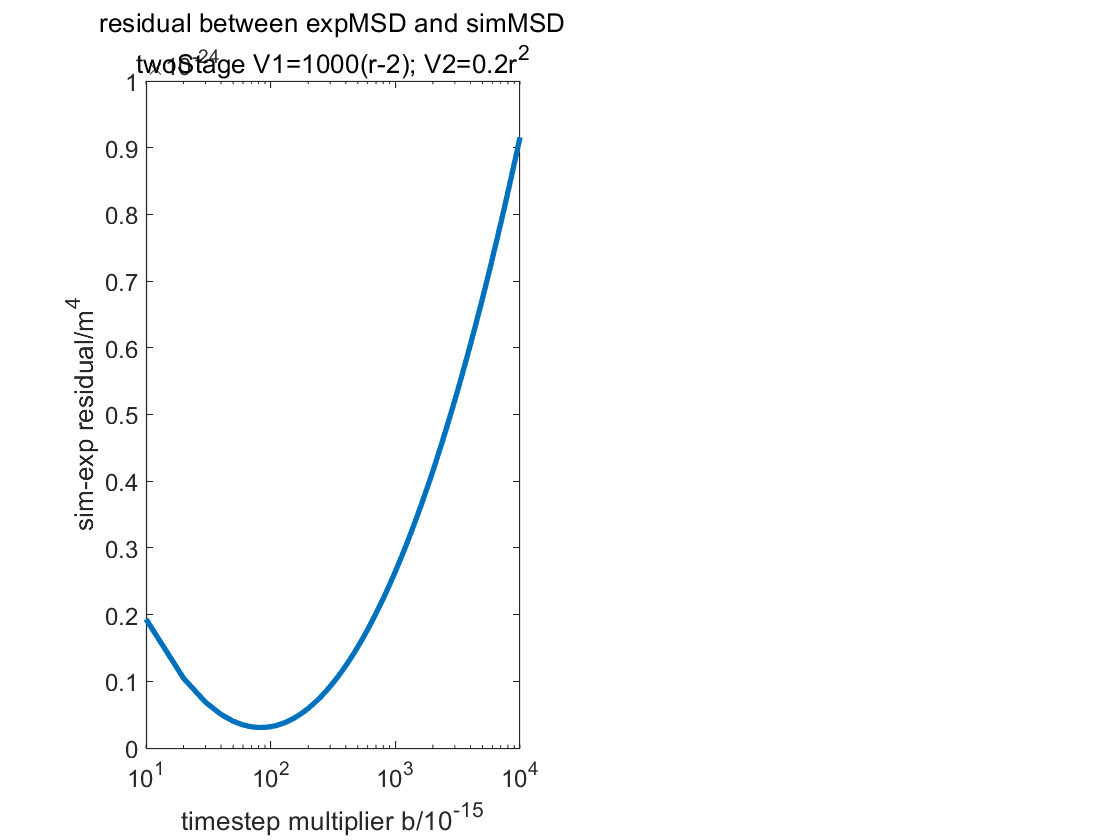

figure
subplot(1,2,1)
plot(b_scale,residual_list,'LineWidth',2)
title({'residual between expMSD and simMSD';simMSDType},"FontSize",15)
set(gca,'xscale','log')
xlabel('timestep multiplier b/10^{-15}')
ylabel('sim-exp residual/m^4')

show the exp MSD and sim MSD

first calculate sim MSD

%b_min=1e2;
sim_list=[];
%b_min=100000;
for t=1:max(t_exp)/100:max(t_exp)
    sim_list=[sim_list,2.56e-14*fun(a,t*b_min)];
end

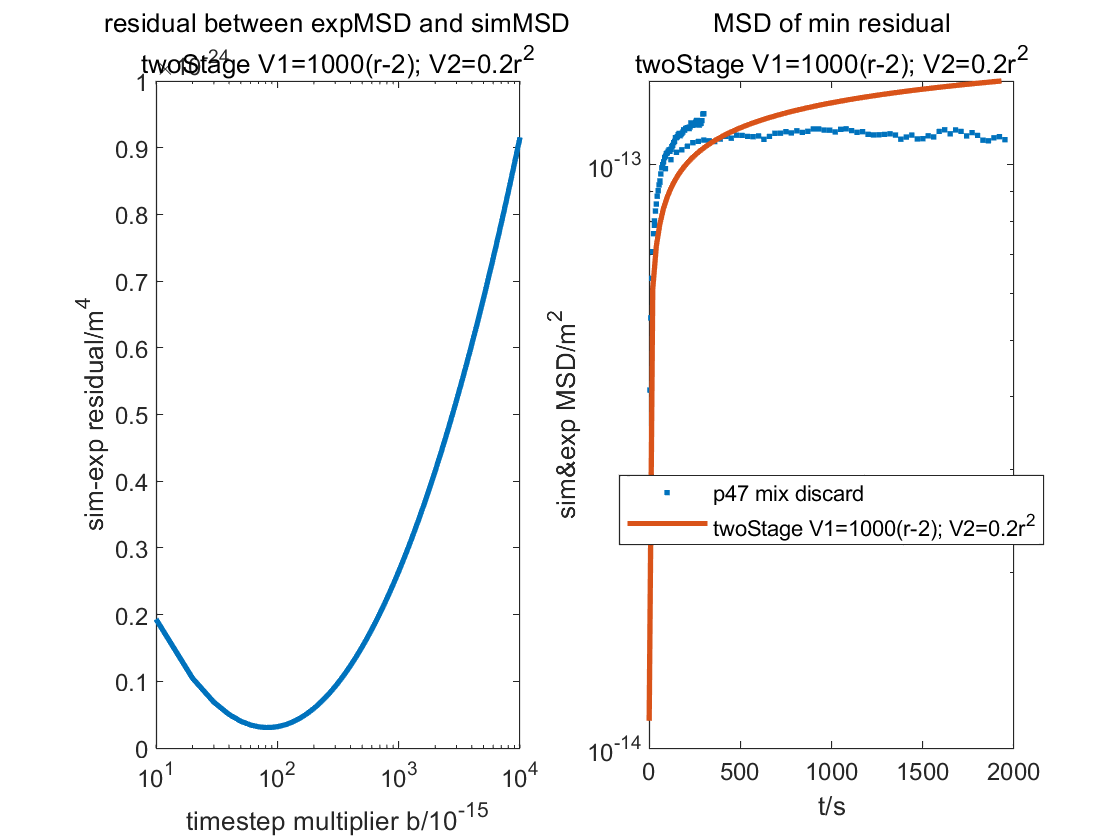

subplot(1,2,2);
plot(t_exp,MSD_exp*1e-18,'.','DisplayName',expMSDType)
hold on
plot(1:max(t_exp)/100:max(t_exp),sim_list,'DisplayName',simMSDType,'LineWidth',2)
title({'MSD of min residual';simMSDType},"FontSize",15)
xlabel('t/s')
ylabel('sim&exp MSD/m^2')
set(gca,'yscale','log')
legend('Location',"best")